load("dataset.mat")


$$$Q= mc(T_{in} -T_{f})\\$
$T_{f}   $      $\epsilon$                  $\mathcal{N}(96,6.25)\\ $
$T_{in} =78; m=10; c=0.1$

E  $ \,  (Q) $=  $mcT_{in} -$$mc$E$( T_{f})\\$
E $\,    (Q^2)$= E[$(mc(T_{in} -T_{f})^2]\\

Var   (Q)= E(Q^2)-[E(Q)]^2


$$


sigma_Q=[];
for i=10:10:N
 sigma_Q=[sigma_Q;var(Q(1:i))];
end

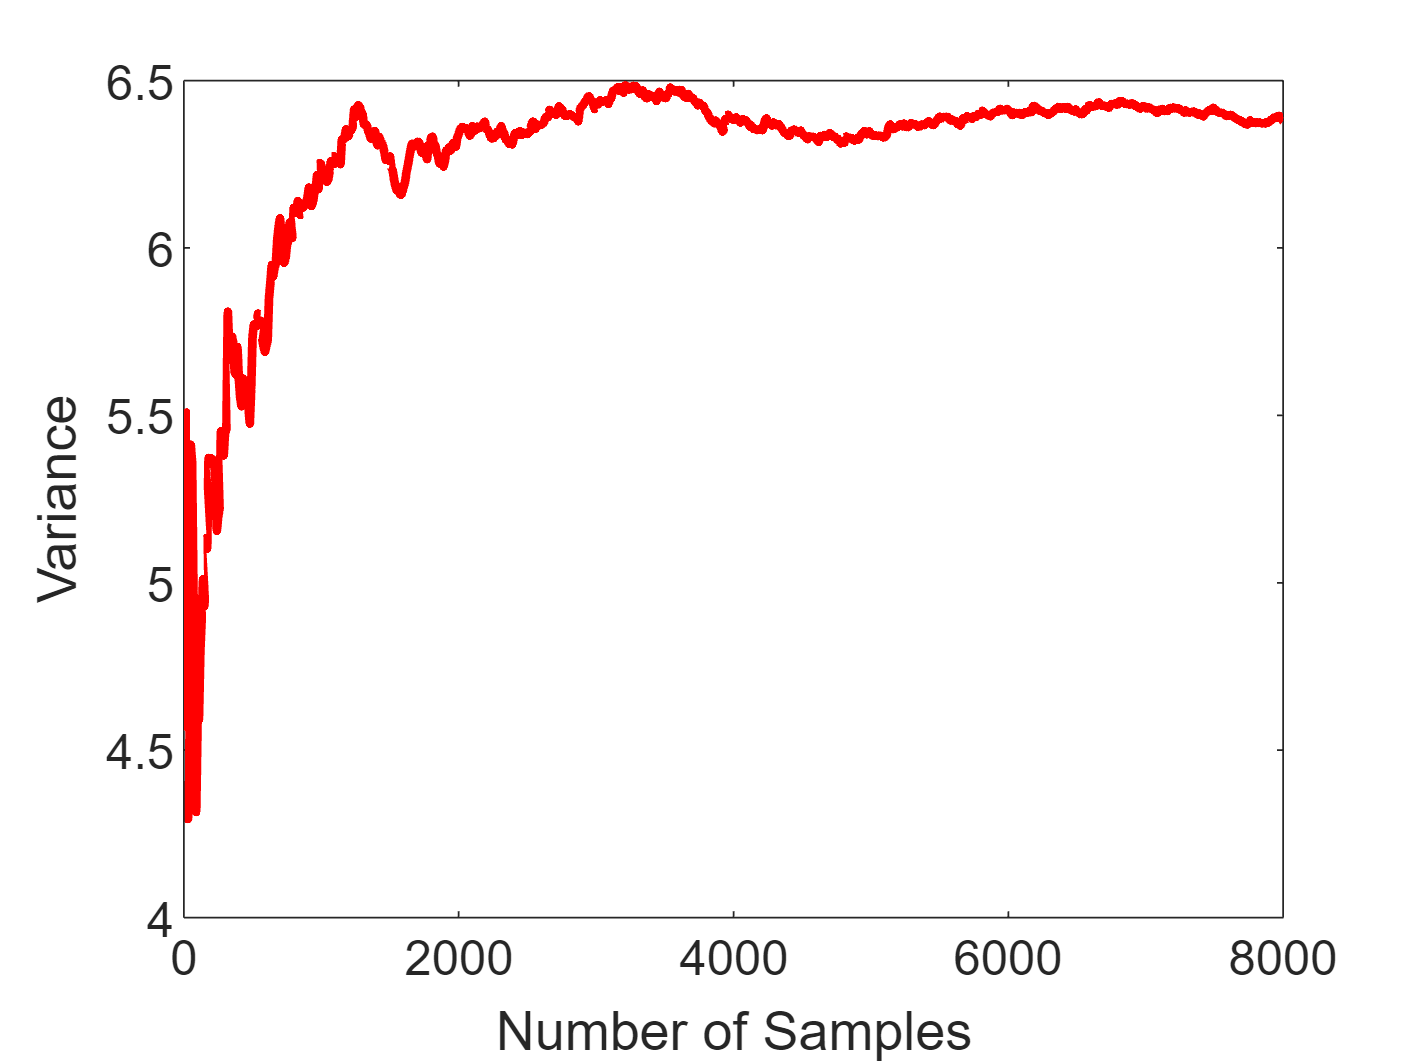

samples=10:10:N;
plot(samples,sigma_Q,LineWidth=2.5,Color='red')
xlabel('Number of Samples', 'FontSize', 16); 
ylabel('Variance', 'FontSize', 16); 
set(gca, 'FontSize', 14);

We observe that as we consider more samples we tend closer towards the true variance of the data. Hence sample variance approaches population variance.

Here, $$Q_{meas}= Q +\epsilon$

The SNR in this measurement is considerably high as compared to the measurement taken in next section.

sigma_Q_meas=[];

for i=10:10:N
 sigma_Q_meas=[sigma_Q_meas;var(Q_meas(1:i))];
end

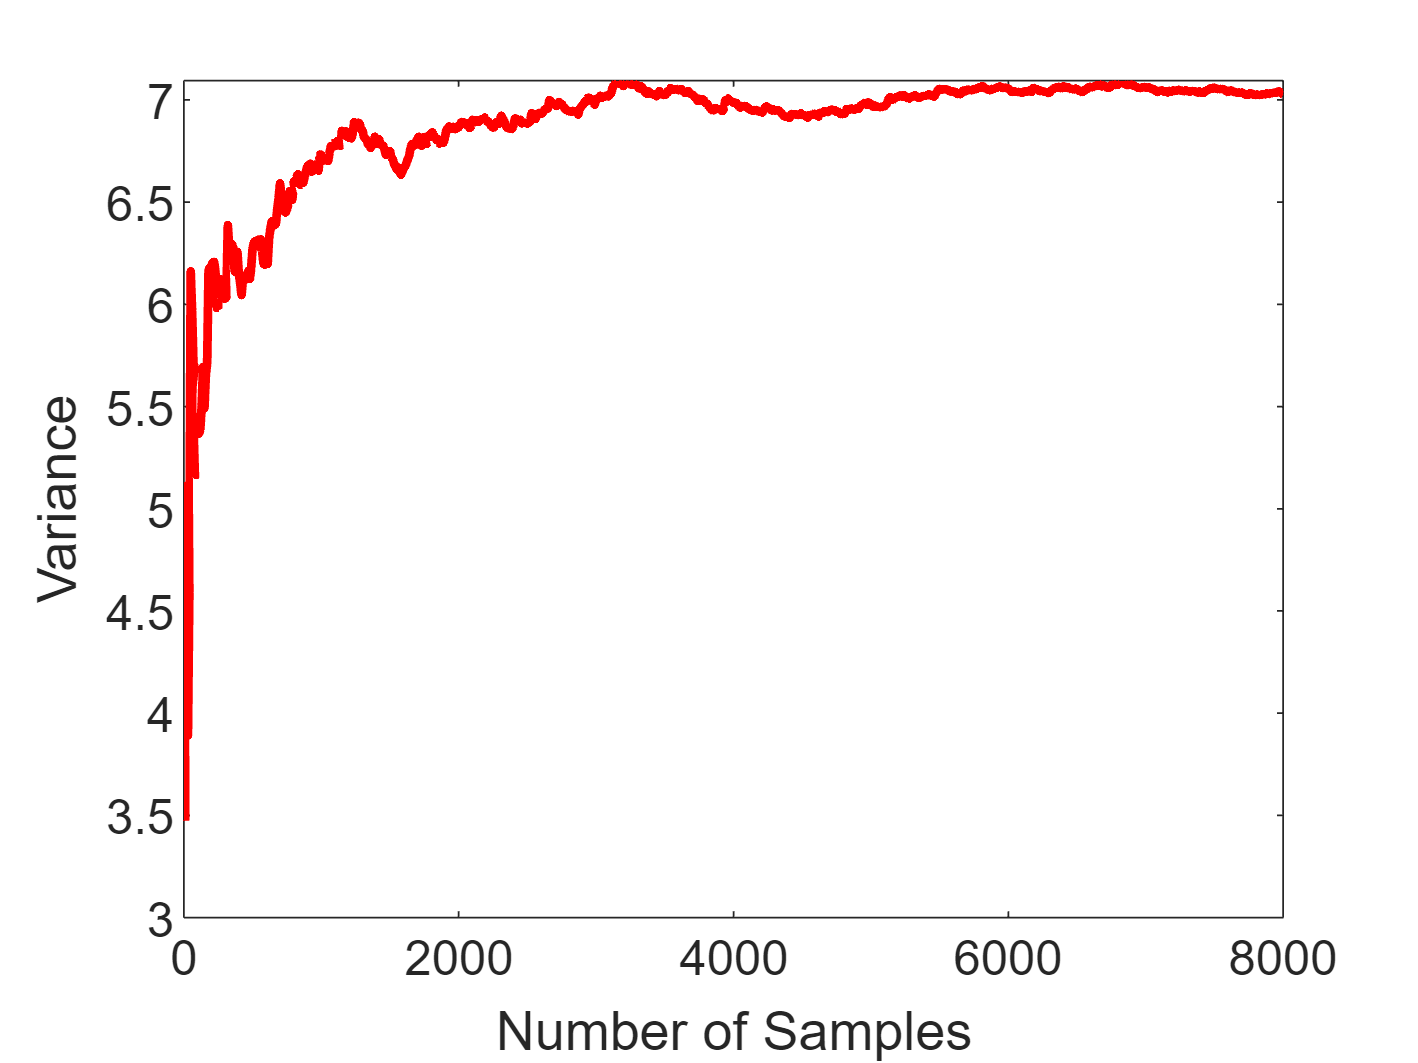

samples=10:10:N;
plot(samples,sigma_Q_meas,LineWidth=2.5,Color='red')
xlabel('Number of Samples', 'FontSize', 16); 
ylabel('Variance', 'FontSize', 16); 
set(gca, 'FontSize', 14);

In the above graph we can observe due to the noise in measurement the variance does not converge to the true variance of data, additional randomness has been incorporated due to the measurement noise.

In the following section:


$$$Q_{meas2}= Q +\epsilon_{2}$$


The SNR is much lower.

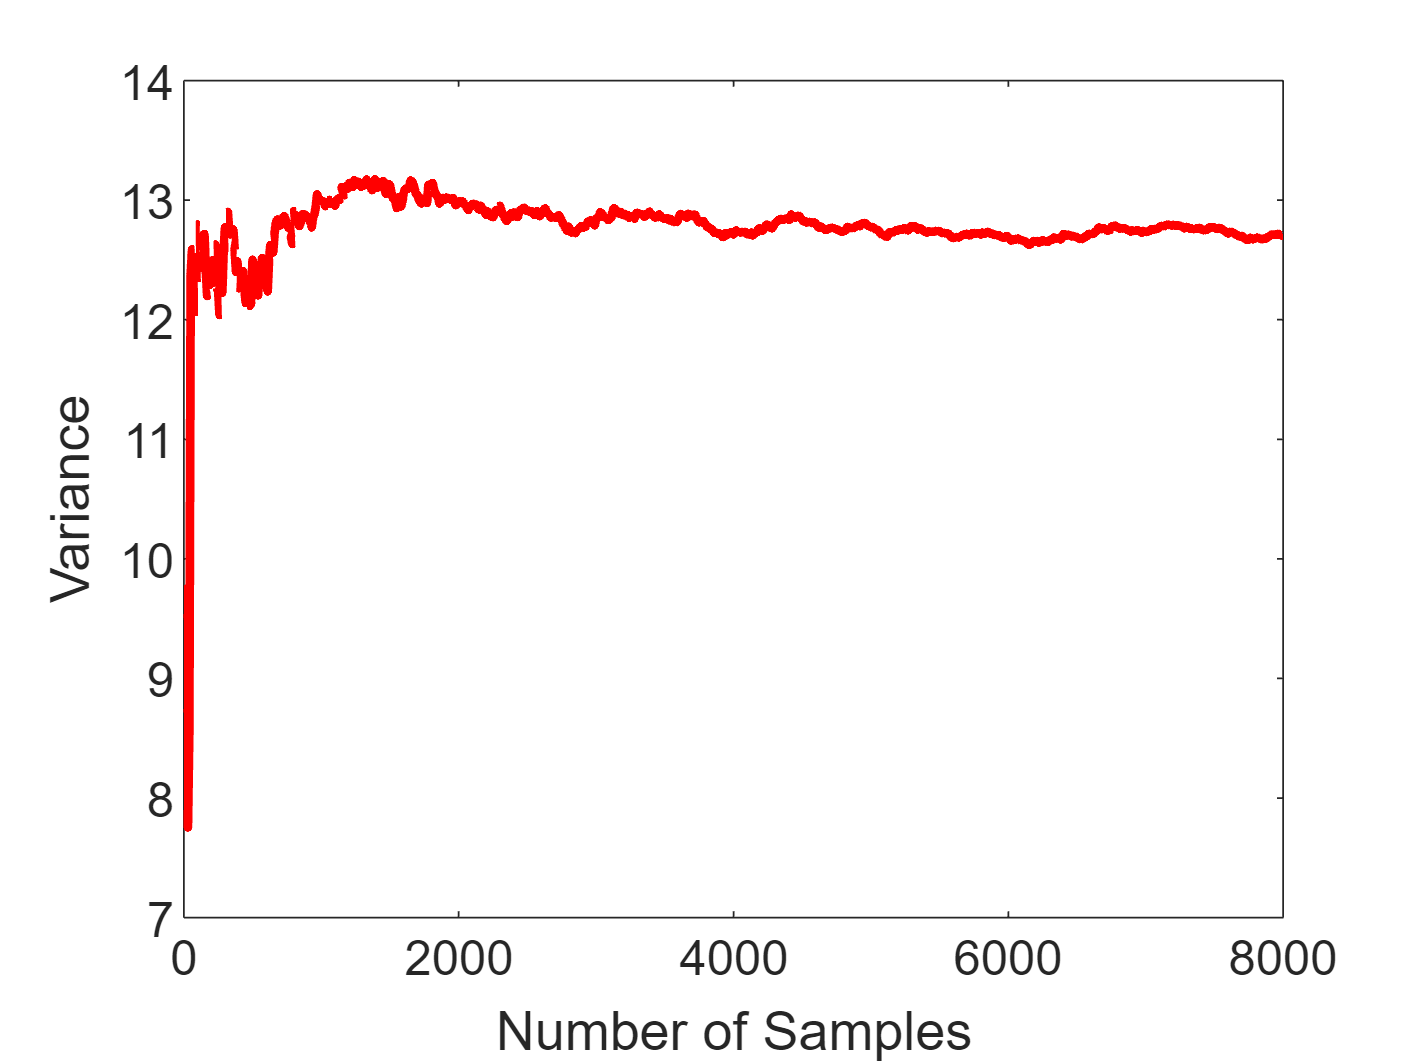

sigma_Q_meas2=[];

for i=10:10:N
 sigma_Q_meas2=[sigma_Q_meas2;var(Q_meas2(1:i))];
end
samples=10:10:N;
plot(samples,sigma_Q_meas2,LineWidth=2.5,Color='red')
xlabel('Number of Samples', 'FontSize', 16); 
ylabel('Variance', 'FontSize', 16); 
set(gca, 'FontSize', 14);

However, Covariance of X and Y remains almost unchanged even after adding noise.

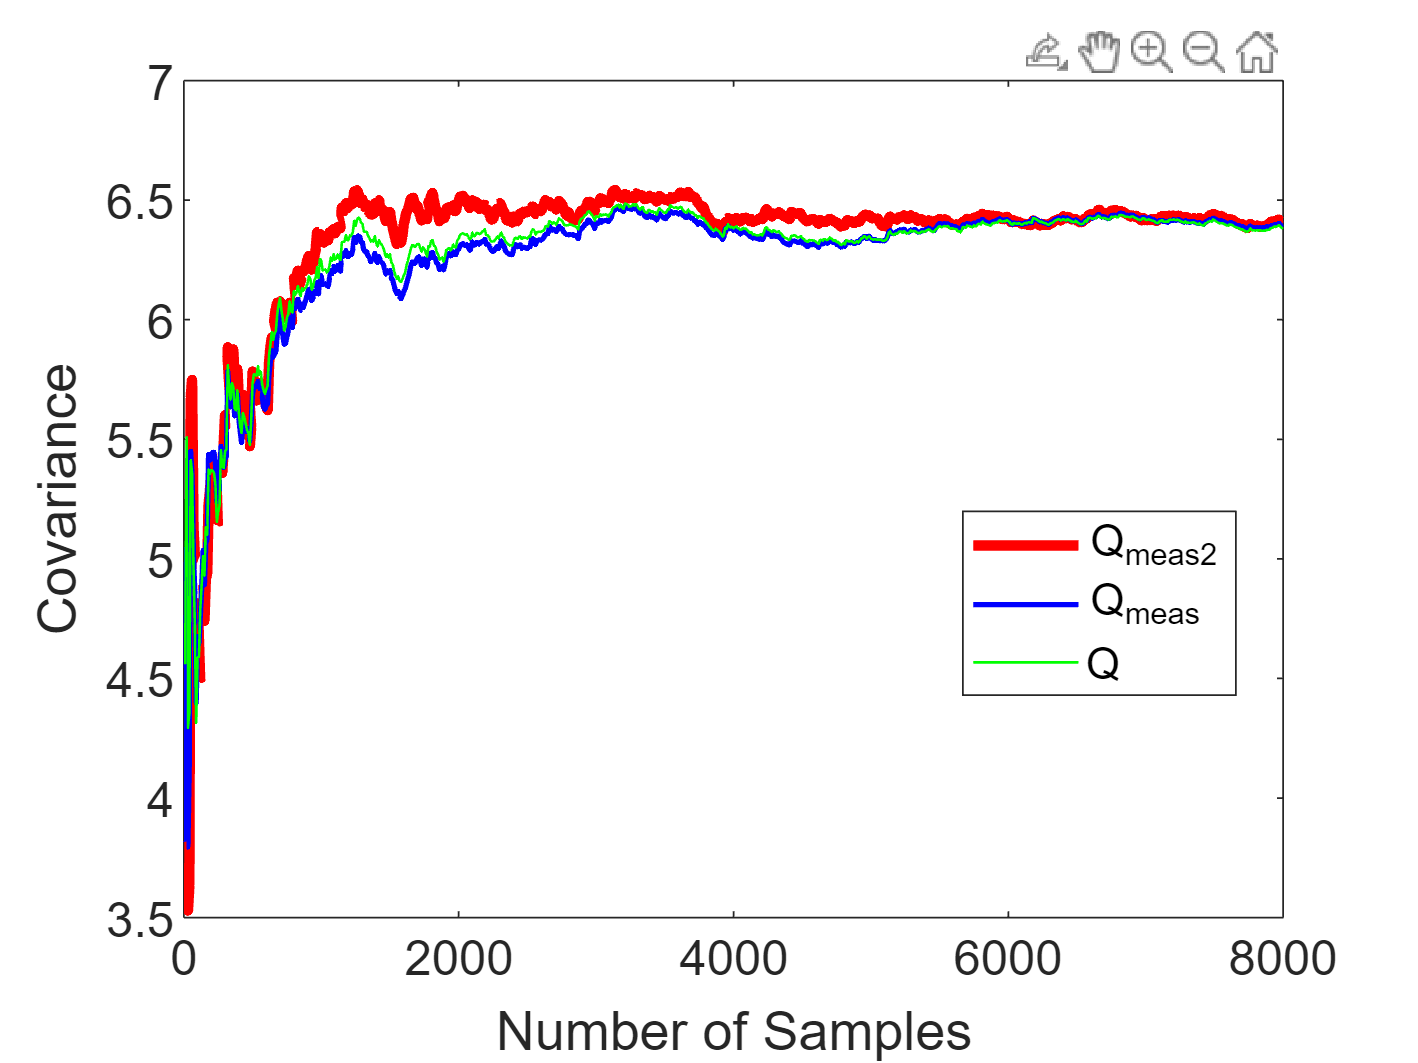

sigma_TQ_meas2=[];
sigma_TQ_meas1=[];
sigma_TQ=[];
for i=10:10:N
 a=cov(Tf(1:i),Q_meas2(1:i));
 sigma_TQ_meas2=[sigma_TQ_meas2;a(1,2)];
 a=cov(Tf(1:i),Q_meas(1:i));
 sigma_TQ_meas1=[sigma_TQ_meas1;a(1,2)];
 a=cov(Tf(1:i),Q(1:i));
 sigma_TQ=[sigma_TQ;a(1,2)];
end
samples=10:10:N;
figure
plot(samples,sigma_TQ_meas2,LineWidth=3,Color='red')
hold on;
plot(samples,sigma_TQ_meas1,LineWidth=1.5,Color='blue')
plot(samples,sigma_TQ,LineWidth=0.75,Color='green')
xlabel('Number of Samples', 'FontSize', 16); 
ylabel('Covariance', 'FontSize', 16); 
set(gca, 'FontSize', 14);
legend('Q_{meas2}','Q_{meas}','Q',Location='best')

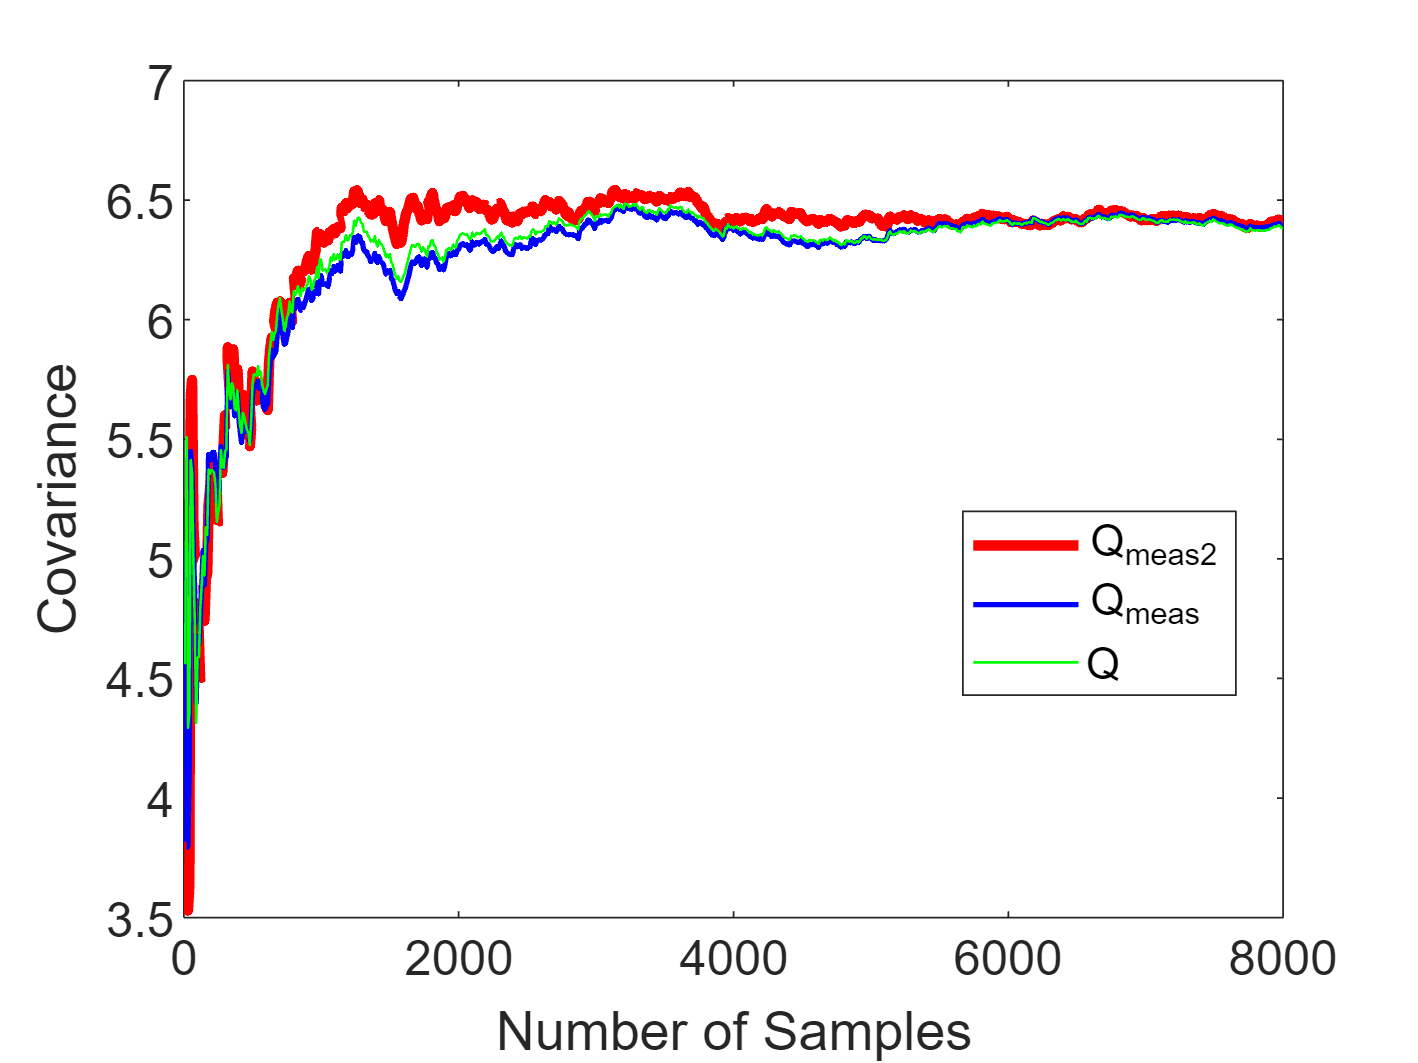

hold off;

figure

Correlation of X,Y changes as noise is added.

 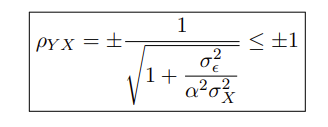

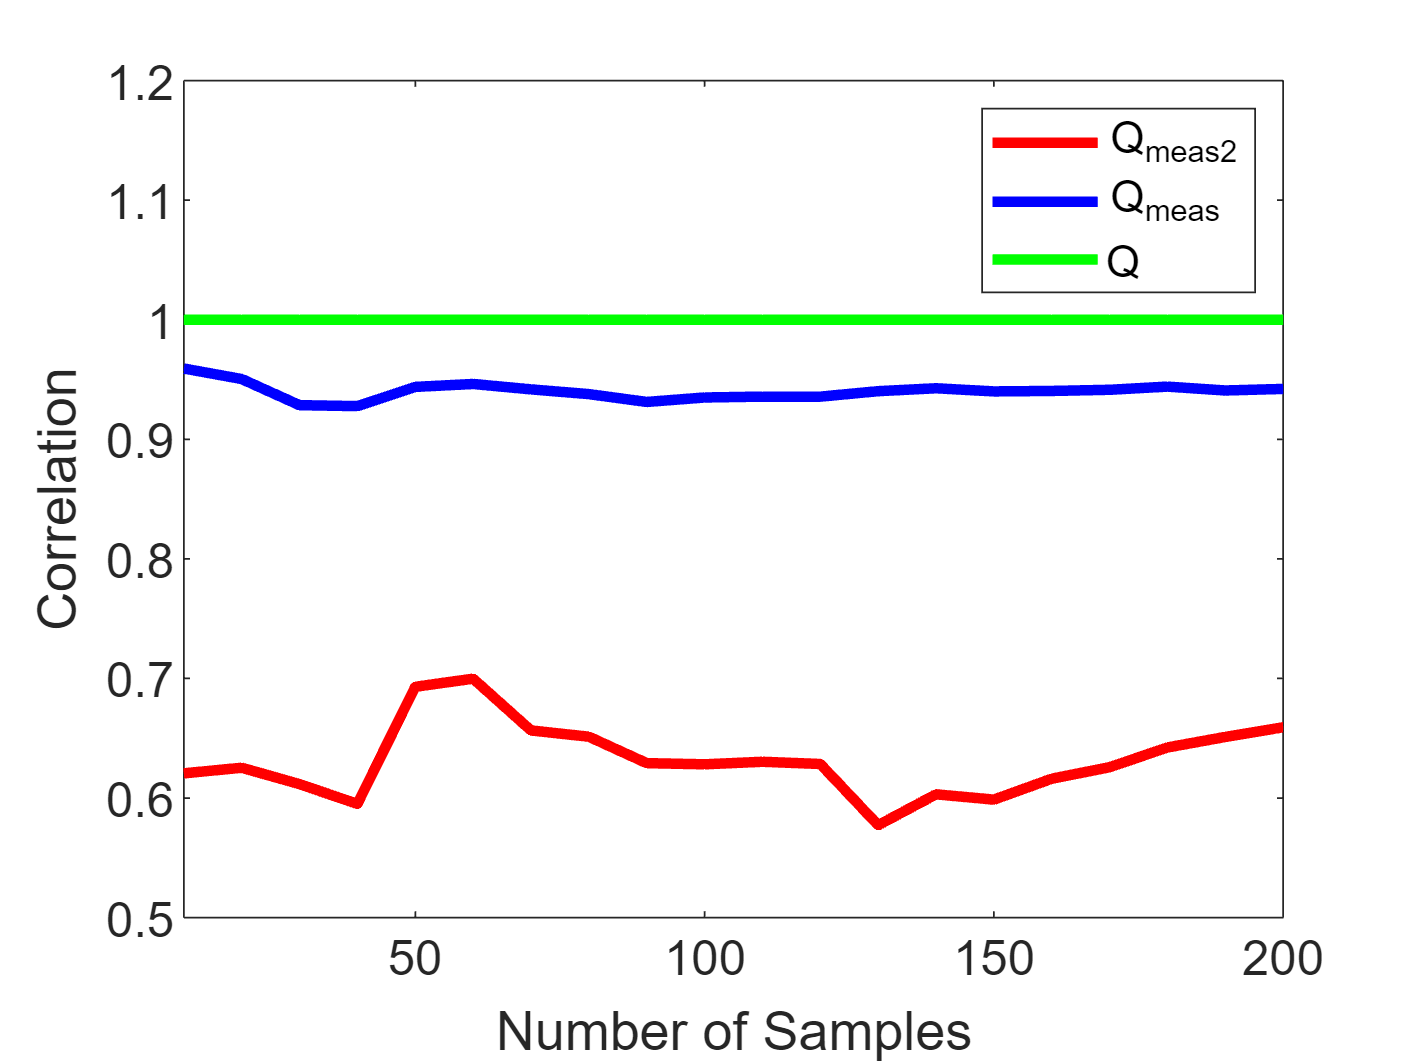

sigma_TQ_meas2=[];
sigma_TQ_meas1=[];
sigma_TQ=[];
for i=10:10:N
 a=corr(Tf(1:i),Q_meas2(1:i));
 sigma_TQ_meas2=[sigma_TQ_meas2;a];
 a=corr(Tf(1:i),Q_meas(1:i));
 sigma_TQ_meas1=[sigma_TQ_meas1;a];
 a=corr(Tf(1:i),Q(1:i));
 sigma_TQ=[sigma_TQ;a];
end
samples=10:10:N;
plot(samples,sigma_TQ_meas2,LineWidth=3,Color='red')
hold on
plot(samples,sigma_TQ_meas1,LineWidth=3,Color='blue')
plot(samples,sigma_TQ,LineWidth=3,Color='green')

xlabel('Number of Samples', 'FontSize', 16); 
ylabel('Correlation', 'FontSize', 16); 
set(gca, 'FontSize', 14);
legend('Q_{meas2}','Q_{meas}','Q')
ylim([0.5,1.2])
xlim([10,200])
hold off;

## In Class Question:  Calculate SNR of Q_meas and Q_meas2.